# Weather analysis

2024-04-19

## Prepare data

apiKey ="b1b15e88fa797225412429c1c50c122a1";

% Define the location for which you want the weather forecast
cityName = "Muenchen"; 
countryCode = "DE";

% Create the URL for the API call
url = sprintf("http://samples.openweathermap.org/data/2.5/forecast?q=%s,%s&appid=%s", cityName, countryCode, apiKey);
 

% Send the web request to the OpenWeatherMap API
response = webread(url);

% Assuming "response" is the struct obtained from the OpenWeatherMap API
data = parseForecast(response.list);
data = struct2table(data);
if true
    data
end 

data = 36x6 table
            date            temperature     weather      clouds    wind         details     
    ____________________    ___________    __________    ______    ____    _________________

    16-Feb-2017 12:00:00       13.52       {'Clear' }       0      1.81    {'clear sky'    }
    16-Feb-2017 15:00:00       12.51       {'Clear' }       0      1.59    {'clear sky'    }
    16-Feb-2017 18:00:00         3.9       {'Clear' }       0      1.41    {'clear sky'    }
    16-Feb-2017 21:00:00       -0.37       {'Clear' }       0      2.24    {'clear sky'    }
    17-Feb-2017 00:00:00       0.191       {'Clouds'}      76      3.59    {'broken clouds'}
    17-Feb-2017 03:00:00       2.418       {'Rain'  }      76      3.77    {'light rain'   }
    17-Feb-2017 06:00:00       3.

## Modeling

### Model 1: Linear regression

 
X = (1:36);
y = data.temperature;
model1 = fitlm(X,y)

model1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      5.2087        1.36     3.8299    0.00052575
    x1             -0.19549    0.064099    -3.0497     0.0044166


Number of observations: 36, Error degrees of freedom: 34
Root Mean Squared Error: 4
R-squared: 0.215,  Adjusted R-Squared: 0.192
F-statistic vs. constant model: 9.3, p-value = 0.00442

% plot(model1)
save("model1.mat","model1")

### Model 2: Polynomial fitting

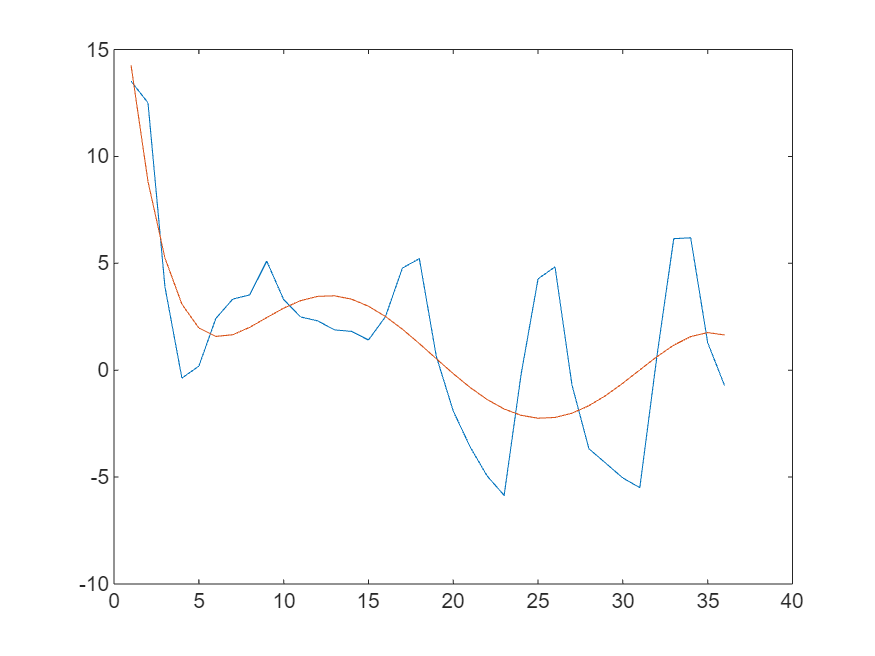

 
n = 6;
X = (1:36);
y = data.temperature;
p = polyfit(X,y,n);
y1 = polyval(p,X);
plot(X,y,X,y1)

## Helper function

- [getData.m](matlab:open('getData.m'))

- [parseForecast.m](matlab:open('parseForecast.m'))

function forecastData = parseForecast(responseList)
    % Initialize an array of structs to hold the parsed forecast data
    forecastData = struct("date", {}, "temperature", {}, "weather", {}, "clouds", {}, "wind", {}, "details", {});

    % Loop through each entry in the responseList cell array
    for i = 1:length(responseList)
        % Get the current forecast struct
        forecastStruct = responseList{i};

        % Extract the date and time of the forecast
        forecastData(i).date = datetime(forecastStruct.dt, "ConvertFrom", "posixtime");

        % Extract main forecast data like temperature
        forecastData(i).temperature = forecastStruct.main.temp - 273.15;

        % Extract weather conditions
        forecastData(i).weather = forecastStruct.weather(1).main;

        % Extract cloud data
        forecastData(i).clouds = forecastStruct.clouds.all;

        % Extract wind data
        forecastData(i).wind = forecastStruct.wind.speed;

        % Extract additional details if needed
        forecastData(i).details = forecastStruct.weather(1).description;
    end
end

- [linReg.m](matlab:open('linReg.m'))

- Export Live Script to Markdown

- Add Open in MATLAB Online badge